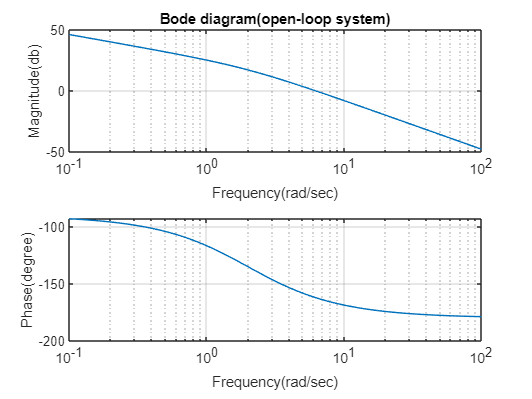

clc;clear all;
num=40;
den=([1 2 0]);
sys=tf(num,den);
[Gm,Pm,Wcp,Wcg]=margin(sys);
w=logspace(-1,2,100);
[mag,phase]=bode(num,den,w);
figure(1);
subplot(2,1,1);
semilogx(w,20*log10(mag));
title('Bode diagram(open-loop system)');
xlabel('Frequency(rad/sec)');
ylabel('Magnitude(db)');
grid;
subplot(2,1,2);
semilogx(w,phase);grid;
xlabel('Frequency(rad/sec)');
ylabel('Phase(degree)');

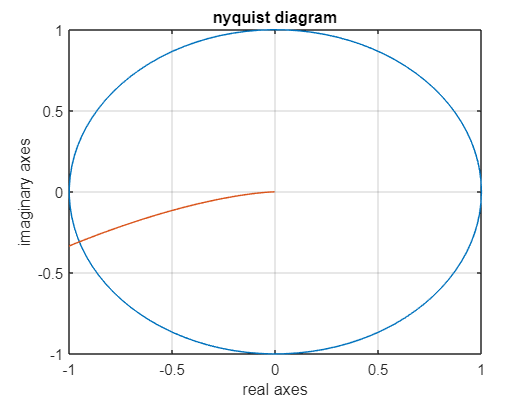

figure(2);
w2=linspace(0,2*pi,100);
ejw=exp(j*w2);
r1=real(ejw);
i1=imag(ejw);
[r,i]=nyquist(num,den,w);
plot(r1,i1,r,i);
axis([-1 ,1 ,-1,1]);
grid
title('nyquist diagram');
xlabel('real axes');
ylabel('imaginary axes');

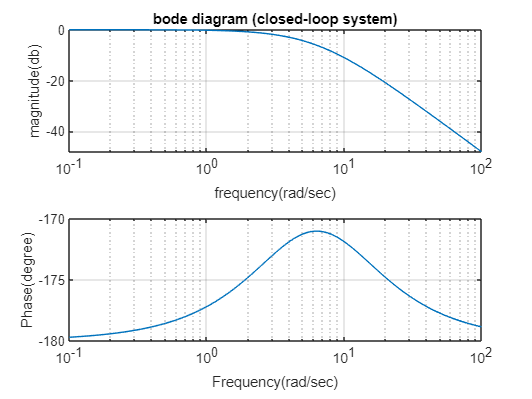


figure(4);
[num2,den2]=cloop(num,den,1);
[mag2,phase2]=bode(num2,den2,w);
subplot(2,1,1)
semilogx(w,20*log10(mag2));grid;
title('bode diagram (closed-loop system)');
xlabel('frequency(rad/sec)');
ylabel('magnitude(db)');
subplot(2,1,2);
semilogx(w,phase2);grid;
xlabel('Frequency(rad/sec)');
ylabel('Phase(degree)');

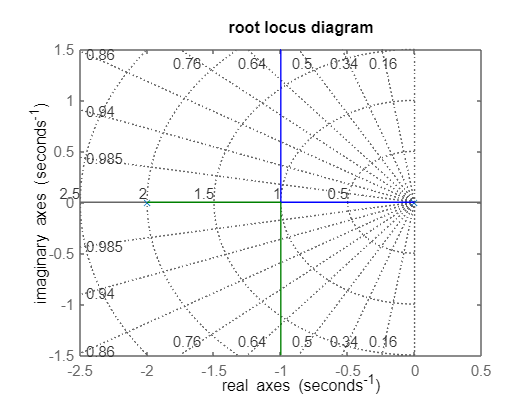


figure(3);
rlocus(num,den);
sgrid;
title('root locus diagram');
xlabel('real axes');
ylabel('imaginary axes');

figure(5)
sys=tf(num,den);
plot(t,yout)

Unrecognized
function
or
variable
't'.

grid on
title('step response')
